clear, close all, clc

Et raketbrændstof laves af to dele. Det antages, at styrken af bindingerne, y, er lineært med stoffernes alder x, når brændstoffet laves.

load('dataset_problem_11_11.mat')
x_bar = sum(data(:,2))/length(data)

x_bar = 13.3375

Y_bar = sum(data(:,1))/length(data)

Y_bar = 1.4695e+04

Opgave a)

Tegn et scatterplot af dataene. Virker en simpel lineær regression korrekt at anvende?

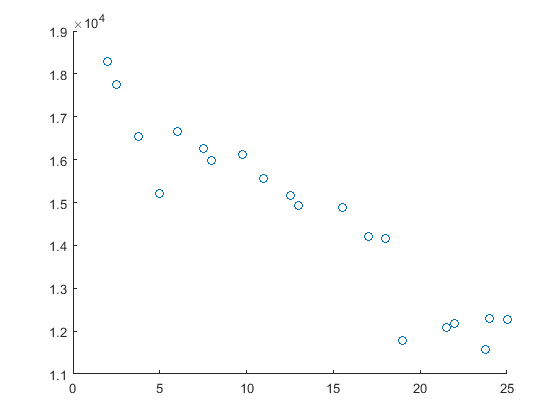

scatter(data(:,2),data(:,1))

Det virker lineært.

Opgave b)

Brug least-squares til at finde parametrene. Estimer variansen.

% β_1,hat = sum((xi-x_bar)*(Yi-Y_bar))/(sum(xi-x_bar)^2)
%         = sXY/sXX

sum1 = 0;
sum2 = 0;
for i = 1:length(data)
    sum1 = sum1 + (data(i,2)-x_bar)*(data(i,1)-Y_bar);
    sum2 = sum2 + (data(i,2)-x_bar)^2;
end
beta1_hat = sum1/sum2

beta1_hat = -254.5443

beta0_hat = Y_bar - beta1_hat*x_bar

beta0_hat = 1.8090e+04


% Alternativ: Brug regress(y,x)
[beta,~,r] = regress(data(:,1),[ones(size(data)) data(:,2)])

beta = 	1.0e+04 *

         0
    1.8090
   -0.0255


r = 	1.0e+03 *

    0.7389
   -0.4744
   -0.0856
    0.4496
   -1.5973
   -1.4756
    0.3239
    0.3008
    0.0760
    0.2692



% SSE = sum(Yi-(beta0_hat+beta1_hat*xi)^2)
% σ^2 = SSE/df
% df = n - 2
df = length(data)-2;
sum3 = 0;
for i = 1:length(data)
    sum3 = sum3 + (data(i,1) - (beta0_hat+beta1_hat*data(i,2)))^2;
end
sigma_squared_hat = sum3/df

sigma_squared_hat = 4.6101e+05


% Alternativ: Brug residual fra regress
SSE = sum(r.*r);
sigma_squared_hat = SSE/df

sigma_squared_hat = 4.6101e+05

Opgave c)

Estimer middelværdien af bindingsstyrken for et brændstof, hvor stofferne er 20 uger gamle.

Y_20 = beta0_hat + beta1_hat*20

Y_20 = 1.2999e+04

Opgave d)

Få fat i alle fittede værdier Y_hat, hvor der er en tilhørende x-værdi i datasættet. Plot Y_hat mod yi og kommenter på, hvordan det burde se ud, hvis sammenhængen var perfekt. Indikerer dette plot, at alder er en god indikator af styrke?

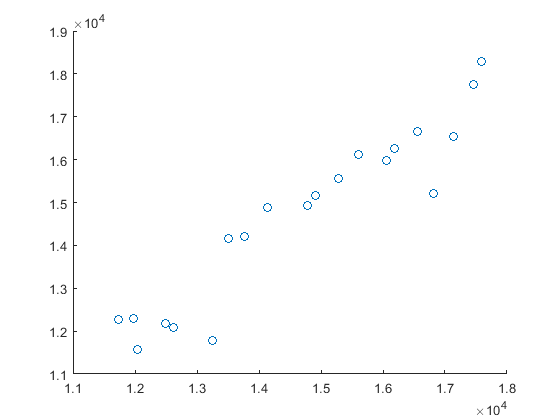

Y_hats = zeros(1,length(data));
for i = 1:length(data)
    Y_hats(i) = beta0_hat + beta1_hat * data(i,2);
end
scatter(Y_hats,data(:,1))

Værdierne burde ligge på en perfekt linje, så alle datapar er identiske, men plottet indikerer stadig, at der er sammenhæng og alderen derfor er en god indikator.